# Lab 4 - MATLAB Functions

Pierce Alvir

## Examples of Computing Functions

x=-5:0.01:5;
% creates a vector of x values spaced every 0.01 starting at -5 and ending at 5
y=x.^2 + 3*x +2;
% computes the quadratic s values at each value in vector of x 
% and places them in the vector y
t=0:0.01:5; % create a vector of time points from 0 seconds to 5 seconds
y=t./(2+sin(5*pi*t)); % note the “dot divide”!!!

## Plotting Mathematical Functions

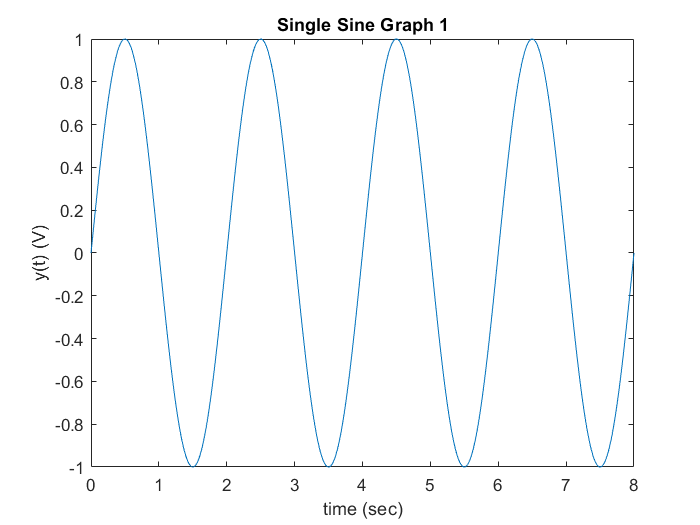

t=0:0.01:8; % creates a vector of times spaced every 1/100th of a second
fo=1/2; % defines a frequency corresponding to the 2 sec period
s=sin(2*pi*fo*t); % computes the value of the sinewave at all the times in t
plot(t,s) % plots the sinewave vs. t; this should open a window for the figure
title('Single Sine Graph 1')
xlabel('time (sec)') %Adds a label to the horizontal axis
ylabel('y(t) (V)') %Here we are assuming that our function has units of volts

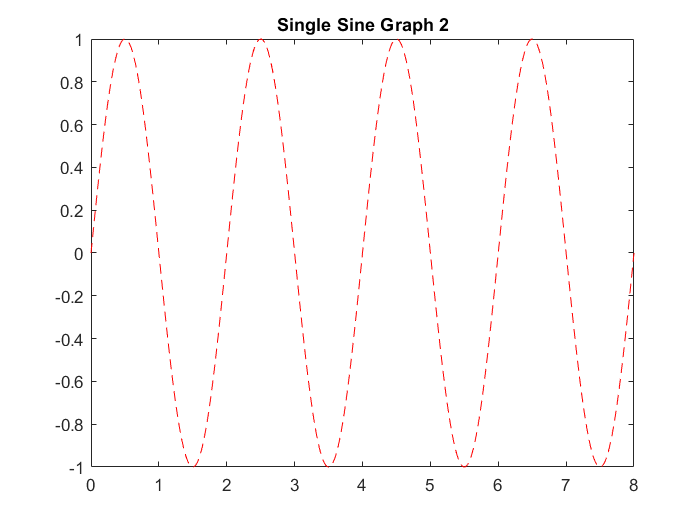

%used help plot to figure out how to plot red dashed lines
plot(t,s,'r--') %same plot as before but with a red dashed line
title('Single Sine Graph 2')

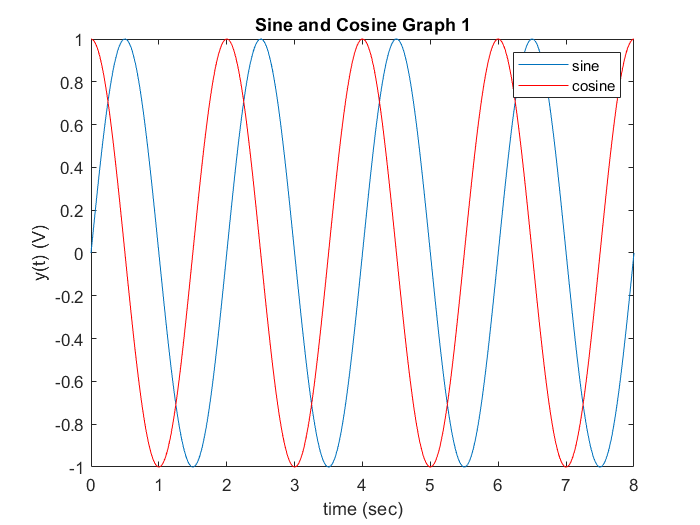

xlabel('time (sec)') %Adds a label to the horizontal axis
ylabel('y(t) (V)') %Here we are assuming that our function has units of volts

t=0:0.01:8; % creates a vector of times spaced every 1/100th of a second
fo=1/2; % defines a frequency corresponding to the 2 sec period
s=sin(2*pi*fo*t); % computes the value of the sinewave at all the times in t
plot(t,s) % plots the sinewave vs. t; this should open a window for the figure
hold on % Turns on hold
c=cos(2*pi*fo*t); % computes the value of the sinewave at all the times in t
plot(t,c,'r')
title('Sine and Cosine Graph 1')
xlabel('time (sec)') %Adds a label to the horizontal axis
ylabel('y(t) (V)') %Here we are assuming that our function has units of volts
hold off %Turns off hold
legend('sine','cosine')

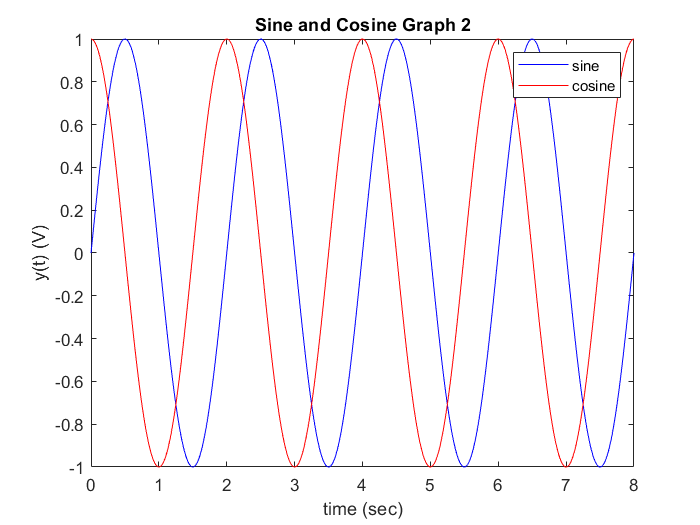


%same plot as above making multiple curves at once
t=0:0.01:8; % creates a vector of times spaced every 1/100th of a second
fo=1/2; % defines a frequency corresponding to the 2 sec period
s=sin(2*pi*fo*t); % computes the value of the sinewave at all the times in t
c=cos(2*pi*fo*t); % computes the value of the sinewave at all the times in t
plot(t,s,'b',t,c,'r')
title('Sine and Cosine Graph 2')
xlabel('time (sec)') %Adds a label to the horizontal axis
ylabel('y(t) (V)') %Here we are assuming that our function has units of volts
legend('sine','cosine')

## Using Poly Equi Function

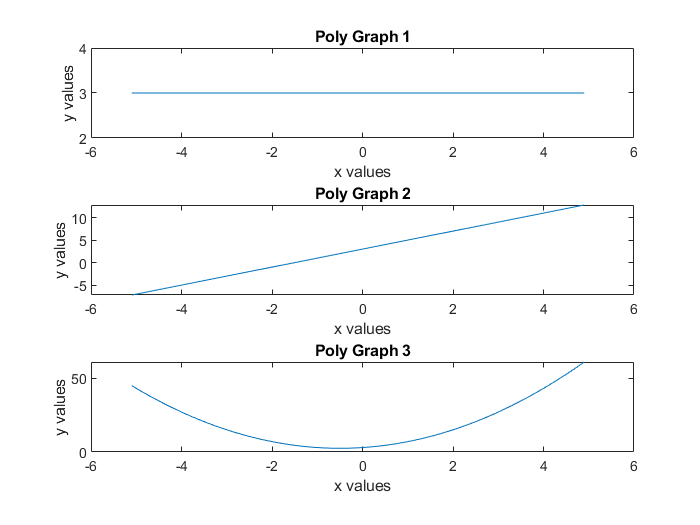

[y_0,x_0] = poly_equi(0,3,-5.1,5.0,0.2);
[y_1,x_1] = poly_equi(1,[3 2],-5.1,5.0,0.2);
[y_2,x_2] = poly_equi(2,[3 2 2],-5.1,5.0,0.2);
%three calculations done using the function
subplot(3,1,1) %allows for multiple graphs to be in one figure
plot(x_0,y_0) %plots each graph from the function calculations
title('Poly Graph 1')
xlabel('x values')
ylabel('y values')
subplot(3,1,2)
plot(x_1,y_1)
title('Poly Graph 2')
xlabel('x values')
ylabel('y values')
subplot(3,1,3)
plot(x_2,y_2)
title('Poly Graph 3')
xlabel('x values')
ylabel('y values')

## Quadratic Function

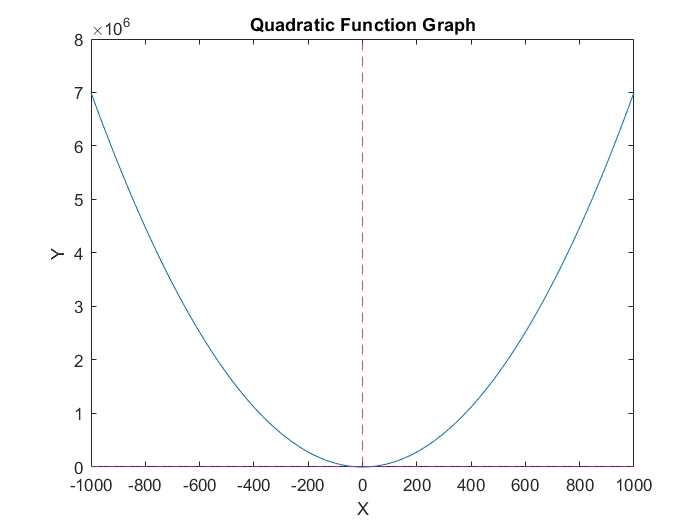

a_in = input('Enter a: '); %gets user input for the function
b_in = input('Enter b: ');
c_in = input('Enter c: ');
step = input('Enter step for x: ');
% i input a=7, b=3, c=4, and step=10
% function has plotting inside it and 
% returns the min/max values for x and y
[x_minmax, y_minmax] = quad(a_in,b_in,c_in,step); 